Non-Linear System

%Define Physical Parameters
M=1.1911;
m=0.23;
l=0.3302;
g=9.8;
alpha1=1.8;
alpha2=10.9;

%Declare Symbolic Real Variables
syms z z_dot theta theta_dot u real
syms z_ddot theta_ddot real  % Second derivatives

% Assign values to z_ddot and theta_ddot based on the equations
z_ddot = ((-m*l)*sin(theta)*theta_dot^2 + m*g*sin(theta)*cos(theta) + alpha1*u - alpha2*z_dot) / (M +m*sin(theta)^2);
theta_ddot = ((-m*l)*sin(theta)*cos(theta)*theta_dot^2 + (M+m)*g*sin(theta) + (alpha1*u - alpha2*z_dot)*cos(theta)) / (l*(M+m*(sin(theta)^2)));

% Define state vector x
x = [z; z_dot; theta; theta_dot];

% Define state derivative vector f, representing f(x, u)
f = [z_dot; z_ddot; theta_dot; theta_ddot];

Linearize System at Equilibrium 

matlabFunction(eval(f),'Vars',{x,u},'File','cartpend','Outputs',{'xdot'});
%testing
cartpend([0 0 pi/2 0]',1)

ans =                    0
   1.266624445851805
                   0
  29.678982434887946


% Equilibrium state and control
x_bar = [0; 0; 0; 0];
u_bar = 0;

% Compute Jacobian of f with respect to x and evaluate at equilibrium
A = subs(jacobian(f, x), [x; u], [x_bar; u_bar]);

% Compute Jacobian of f with respect to u and evaluate at equilibrium
B = subs(jacobian(f, u), [x; u], [x_bar; u_bar]);

% Convert A and B to numeric matrices
A = double(A);
B = double(B);

% Check controllability
controllability_matrix = ctrb(A, B);
controllability_rank = rank(controllability_matrix);

% Display results
disp(A);

  Columns 1 through 3

                   0   1.000000000000000                   0
                   0  -9.151204768701200   1.892368398958945
                   0                   0                   0
                   0 -27.714127100851606  35.409958809687907

  Column 4

                   0
                   0
   1.000000000000000
                   0



disp(B);

                   0
   1.511208126941483
                   0
   4.576644842342467



disp(controllability_matrix);

   1.0e+03 *

  Columns 1 through 3

                   0   0.001511208126941  -0.013829375017767
   0.001511208126941  -0.013829375017767   0.135216140683653
                   0   0.004576644842342  -0.041881814105896
   0.004576644842342  -0.041881814105896   0.545327862321651

  Column 4

   0.135216140683653
  -1.316646412934689
   0.545327862321651
  -5.230430621358182



disp(controllability_rank);

     4



% Check if the system is controllable
if controllability_rank == size(A, 1)
    disp('The system is controllable.');
else
    disp('The system is not controllable.');
end

The system is controllable.


Eigenvalue Assignment

% Desired eigenvalues for pole placement
desired_eigenvalues = [-5, -5, -5, -5];

% Calculate the gain vector Kplace using acker
K_acker = -acker(A, B, desired_eigenvalues);

% Calculate A + B*K_acker and check eigenvalues
A_plus_BK_acker = A + B * K_acker;
eigenvalues_acker = eig(A_plus_BK_acker);

% Display results for acker
disp(K_acker);

  Columns 1 through 3

  13.934992205215416  17.203549319727887 -45.113536092828802

  Column 4

  -8.051081096485262



disp(eigenvalues_acker);

 -5.001190339133728 + 0.000000000000000i
 -4.999999721889353 + 0.001190060926136i
 -4.999999721889353 - 0.001190060926136i
 -4.998810217087585 + 0.000000000000000i



% Slightly perturb desired eigenvalues for place
perturbed_eigenvalues = [-5.1, -4.8, -4.9, -5.0];

% Calculate the gain vector Kplace using place
K_place = -place(A, B, perturbed_eigenvalues);

% Calculate A + B*K_place and check eigenvalues
A_plus_BK_place = A + B * K_place;
eigenvalues_place = eig(A_plus_BK_place);

% Display results for place
disp(K_place);

  Columns 1 through 3

  13.372241480239701  16.866924500168832 -44.270028763612849

  Column 4

  -7.896227445530121



disp(eigenvalues_place);

  -5.099999999740456
  -5.000000000787431
  -4.899999999208423
  -4.800000000349813



Linear Quadratic Optimal Control

% Define Q and R matrices for KLQR1
q1 = 2; q2 = 1; R1 = 0.2;
Q1 = diag([q1, 0, q2, 0])  % Adjust Q based on system size if necessary

Q1 =      2     0     0     0
     0     0     0     0
     0     0     1     0
     0     0     0     0


K_LQR1 = -lqr(A, B, Q1, R1);

% Calculate eigenvalues for the closed-loop system with KLQR1
A_plus_BK_LQR1 = A + B * K_LQR1;
eigenvalues_LQR1 = eig(A_plus_BK_LQR1);

% Display results for KLQR1
disp(K_LQR1);

  Columns 1 through 3

   3.162277660168314  13.634953023681428 -39.932189779786171

  Column 4

  -7.084451343286614



disp(eigenvalues_LQR1);

  -9.852842225949132
  -6.041413434347349
  -4.551175263498141
  -0.523539726132712



% Define Q and R matrices for KLQR2
q1 = 0.1; q2 = 1; R2 = 1;
Q2 = diag([q1, 0, q2, 0])  % Adjust Q based on system size if necessary

Q2 =    0.100000000000000                   0                   0                   0
                   0                   0                   0                   0
                   0                   0   1.000000000000000                   0
                   0                   0                   0                   0


K_LQR2 = -lqr(A, B, Q2, R2);

% Calculate eigenvalues for the closed-loop system with KLQR2
A_plus_BK_LQR2 = A + B * K_LQR2;
eigenvalues_LQR2 = eig(A_plus_BK_LQR2);

% Display results for KLQR2
disp(K_LQR2);

  Columns 1 through 3

   0.316227766016832  12.264340374317214 -36.856470915421106

  Column 4

  -6.528854262256570



disp(eigenvalues_LQR2);

  -9.950033699213918
  -0.052222329666355
  -5.739391864350835
  -4.755833215987546



Simulation of Linear Controllers and Linearized Plant

K = K_place;
x0 = 2*[0;0;pi/24;0];
out_place = sim('lab3_linear.slx' ,10); %run this in the command window

K = K_LQR1;
x0 = 2*[0;0;pi/24;0];
out_LQR1 = sim('lab3_linear.slx' ,10); %run this in the command window

K = K_LQR2;
x0 = 2*[0;0;pi/24;0];
out_LQR2 = sim('lab3_linear.slx' ,10); %run this in the command window

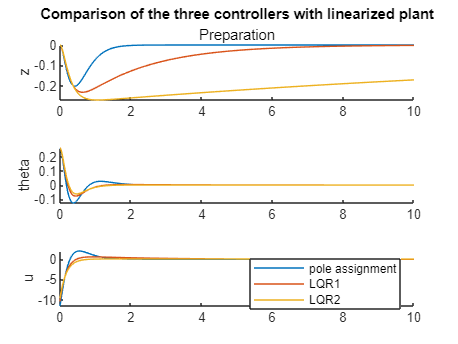

%plots
figure(1)
subplot(311)
title('Comparison of the three controllers with linearized plant')
subtitle('Preparation')
ylabel('z')
hold on
plot(out_place.z)
plot(out_LQR1.z)
plot(out_LQR2.z)
subplot(312)
ylabel('theta')
hold on
plot(out_place.theta)
plot(out_LQR1.theta)
plot(out_LQR2.theta)
subplot(313)
ylabel('u')
hold on
plot(out_place.u)
plot(out_LQR1.u)
plot(out_LQR2.u)
legend('pole assignment','LQR1','LQR2','Location','NorthEast')


% Display matrices A and B of the linearization
disp(A);

  Columns 1 through 3

                   0   1.000000000000000                   0
                   0  -9.151204768701200   1.892368398958945
                   0                   0                   0
                   0 -27.714127100851606  35.409958809687907

  Column 4

                   0
                   0
   1.000000000000000
                   0



disp(B);

                   0
   1.511208126941483
                   0
   4.576644842342467

